# Part 2: Modeling

>>> System specification

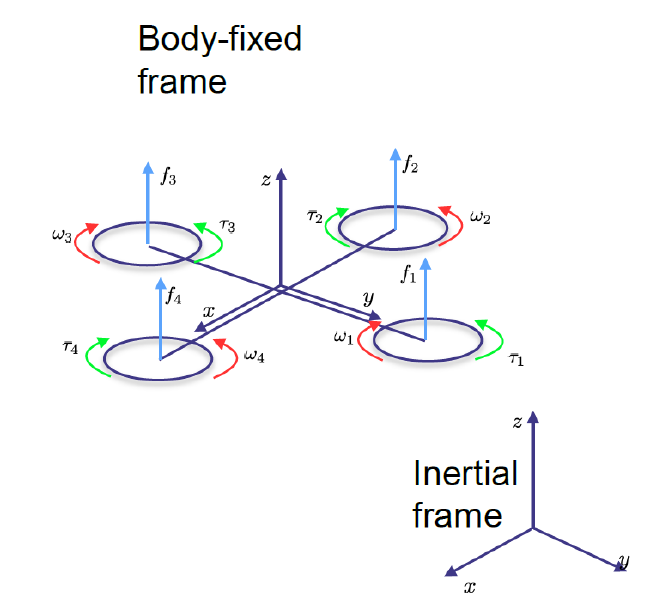

m = 0.5;    % [kg]              the drone mass in the center of gravity of the drone
L = 0.225;  % [m]               length of each arm of the quadrotor frame, i.e. the distance of the motors from the CoG
k = 0.01;   % [N*s^2/rad^2]     the overall aerodynamic coefficient necessary to compute the lift of the propellers
b = 0.001;  % [Nm*s^2/rad^2]    the overall aerodynamic coefficient necessary to compute the drag torque of the propellers
D = diag([0.01, 0.01, 0.01]);
            % [N*s/m]           matrix representing the the drag on the UAV moving in air with velocity p_dot
MoI = diag([3e-6, 3e-6, 1e-5]);
            % [Nm*s^2/rad]      the moment of inertia on the principal axes
Ixx = 3e-6;
Iyy = 3e-6;
Izz = 1e-5;
g = [0, 0, -9.81]';              
            % [m/s^2]            gravity acts along the z-axis of the inertial frame of reference

#### Initial conditions

% [m] position of the CoG of the UAV w.r.t. a fixed inertial frame of reference
p = [0, 0, 0]';         %   [x, y, z]'      

% [m/s] linear velocity of the CoG of the UAV w.r.t. a fixed inertial frame of reference
p_dot = [0, 0, 0]';     %   [x, y, z]'   

% [rad] the representation of the rotation of the body-fixed w.r.t. inertial frame
Theta = [0, 0, 0]';     %   [phi, theta, psi] = [roll, pitch, yaw]

% [rad/s] the angular velocity of the body-fixed frame w.r.t the inertial frame (expressed in body fixed frame)
omega = [0, 0, 0]';

% [rad/s] vector of the angular speed of the four propellers
RPM = [0, 0, 0, 0]';

# `Exercise 2.1 - Modeling with Euler Angles `

## 2.1.1 (NOT USED)

>>> Define the rotation matrix representing the orientation of the body-fixed frame w.r.t. the inertial frame.

The following matrices are for a body-fixed frame with a z-axis pointing downwards as follows (not used in this simulation, you can skip this derivation):

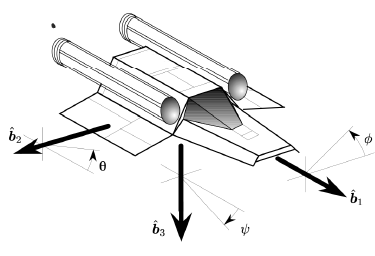

Rotation from inertial frame to body fix frame (following ZYX Euler angles rotation).

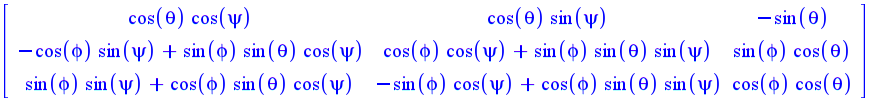

short form:

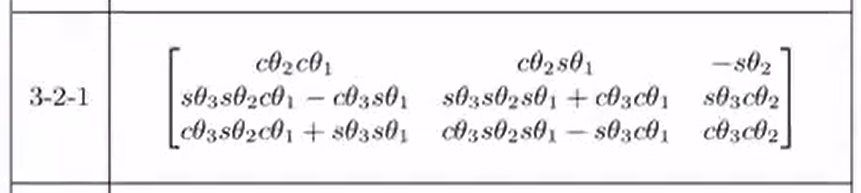

Rotation from body-fixed frame to inertial frame (transpose of the one above):

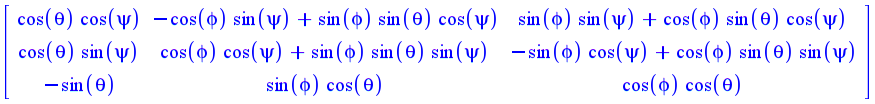

## 2.1.2 (NOT USED)

>>> Define the relation between the angular velocity $\dot{\Theta}$ and the rotational velocity of the body-fixed frame $\omega$ !

For the above rotation (following ZYX Euler angles rotation) the following applies:

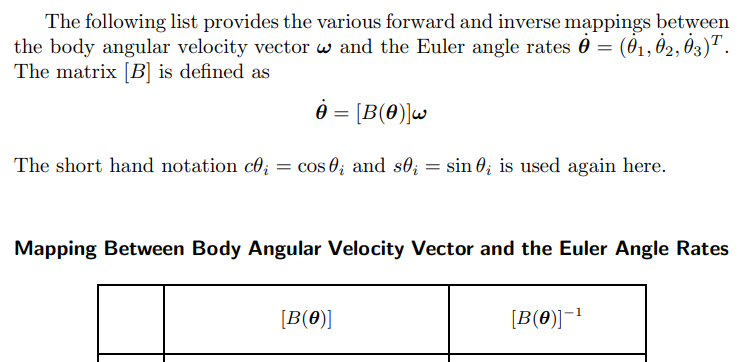

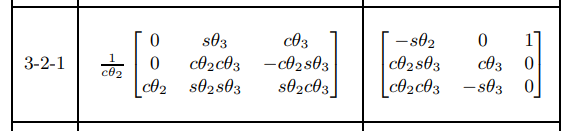

## 2.1.1 & 2.1.2

These are the matrices answering two questions, where rotational matrix has been already represented, as a transformation from body-fixed frame to inertial frame (because we are "undoing" ZYX rotations, by rotating by XYZ:

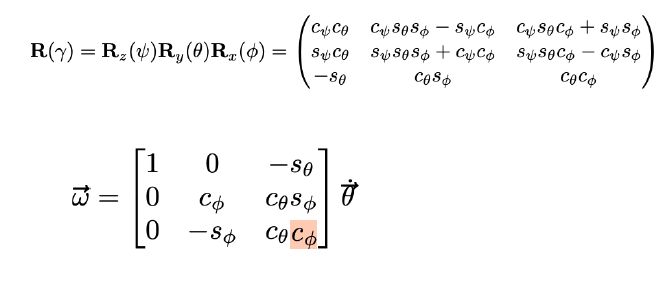

## 2.1.3

>>> Write the linear and angular dynamic equation of the drone in compact form, and clearly show each component of the equation explicitly.

(For details see: [https://andrew.gibiansky.com/blog/physics/quadcopter-dynamics/](https://andrew.gibiansky.com/blog/physics/quadcopter-dynamics/) )

Linear motion equations:

(TB - total thrust, FD - drag force)

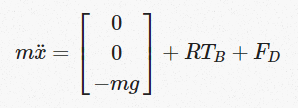            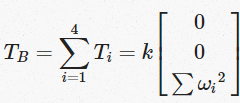            

Angular motion equations:

(omegas with subscripts are the propellar angular speed)

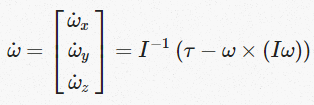                            

Simplifying:

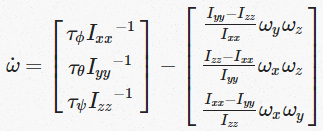

Compact form (x1 - position, x2 - linear velocity, x3 - roll, pitch and yaw, x4 - angular velocity vector):

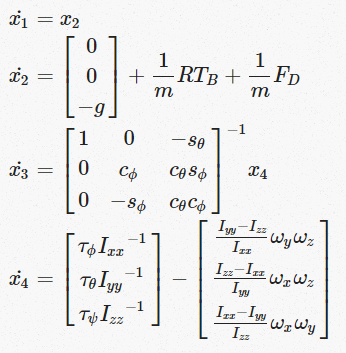

## 2.1.4

>>> Make a MATLAB/Simulink model of the drone, given initial conditions (everything =zero) and report plots of linear and angular positions for the motors speeds as follows... (check below).

TakeStep = 1; %setting TakeStep 1 take the stepinput, setting TakeStep to 0 take the IN
simTime = 10; % 100 seconds

>>>  $\Omega = [0,0,0,0]^T$

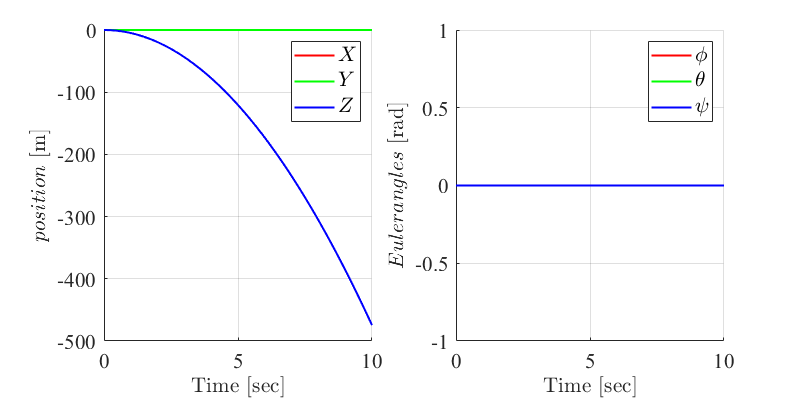

RPM = [0, 0, 0, 0]';
simOut = sim('Exercise_2_2_1_Nonlinear');
plotSimOutput(simOut.yout{1}.Values.Time, simOut.yout{1}.Values.Data) % you can find declaration of a function at the end of the file

There is no thrust, so drone will fall down to infinity, because of gravity. There are no torques acting on the drone either.

>>>  $\Omega = [10000,0,10000,0]^T$

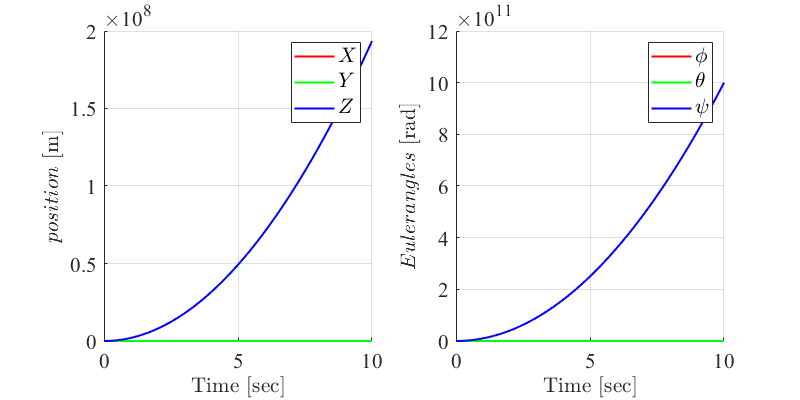

RPM = [10000, 0, 10000, 0]';
simOut = sim('Exercise_2_2_1_Nonlinear');
plotSimOutput(simOut.yout{1}.Values.Time, simOut.yout{1}.Values.Data) % you can find declaration of a function at the end of the file

Thrust is bigger than gravity force and creates upward acceleration (in z-direction) so drone goes upwards unbounded. (The drone itself is in theory stable in x-direction and y-direction) But, because the two motors are spinning in the same direction, and creating the torques of the same direction, the drone spins around the z-axis (in the negative direction).

>>>  $\Omega = [0,10000,0,10000]^T$

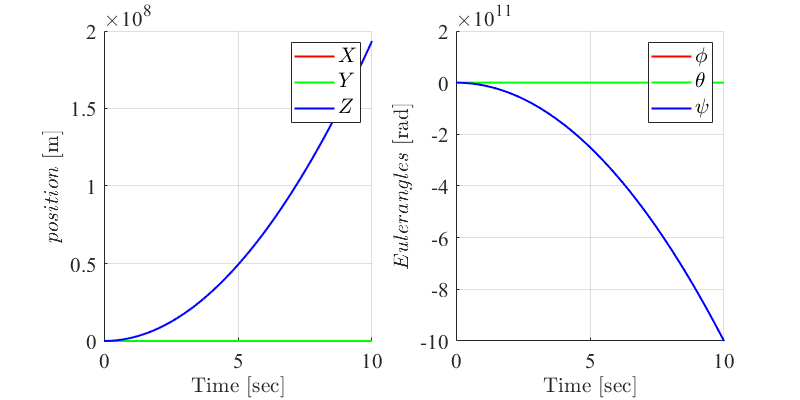

RPM = [0, 10000, 0, 10000]';
simOut = sim('Exercise_2_2_1_Nonlinear');
plotSimOutput(simOut.yout{1}.Values.Time, simOut.yout{1}.Values.Data) % you can find declaration of a function at the end of the file

The same as above, but drone is spinning in the positive directio of z-axis.

# Exercise 2.3 - Linearization in hovering conditions (with Euler angles)

#### Checking how the state looks like

TakeStep = 1; %setting TakeStep 1 take the stepinput, setting TakeStep to 0 take the IN
x = Simulink.BlockDiagram.getInitialState('Exercise_2_2_1_Nonlinear')

x = Simulink.SimulationData.Dataset 'xFinal' with 4 elements

                        Name  BlockPath                                
                        ____  ________________________________________ 
    1  [1x1 State]      ''    ...inear/Angular Acceleration Integrator
    2  [1x1 State]      ''    ..._Nonlinear/Euler Angle Rate Itegrator
    3  [1x1 State]      ''    ...linear/Linera Acceleration Integrator
    4  [1x1 State]      ''    ..._Nonlinear/Linera Velocity Integrator

  - Use braces { } to access, modify, or add elements using index.


#### Finding hovering conditions numerically:

TakeStep = 0; %setting TakeStep 1 take the stepinput, setting TakeStep to 0 take the IN

% initial conditions
% (x1 - position, x2 - linear velocity, x3 - roll, pitch and yaw, x4 - angular velocity vector)

x0 = ones(12,1);   % x1, x2, x3, x4 all of them equal zero
u0 = ones(4,1);     % RPM equal zero
y0 = [];            % position and Euler angles equal zero

% which var to fix
ix = [1,2,3,7,8,9]; % fix all the states
iu = [];            % don't fix the input at all
iy = [];            % no need for fixing the output

% determining the steady state
[xss,uss,yss] = trim('Exercise_2_2_1_Nonlinear',x0,u0,y0,ix,iu,iy);
uss

uss =    11.0736
   11.0736
   11.0736
   11.0736


#### Finding hovering conditions manually

While hovering linear velocity, angular velocity and their derivatives are zero. So x1_dot, x2_dot, x3_dot, x4_dot are zero. On top of that, for simplicity we can assume that position is (0,0,0) and the body-fixed frame is aligned with inertial frame - this gives are R (rotation matric) to be an identity. That being said we only care about thrust being balanced by the gravity. 

When the drone is not moving the drag force is zero as well, because it is relative to the linear velocity. All that being said the above quation simplifies to:


$$0=\left\lbrack \begin{array}{c}
0\\
0\\
-\mathrm{mg}
\end{array}\right\rbrack +k*\left\lbrack \begin{array}{c}
0\\
0\\
\sum \omega_i^2 
\end{array}\right\rbrack$$


It obvious from torque balance that all 4 $\omega
$ need to be the same, so the final value for $\omega
$ in hovering conditions is (assuming omega is possitive):


$$\omega =\sqrt{\frac{\mathrm{mg}}{4k}}$$


rmp_hovering_manually = sqrt(m*(-g(3))/4/k)

rmp_hovering_manually = 11.0736

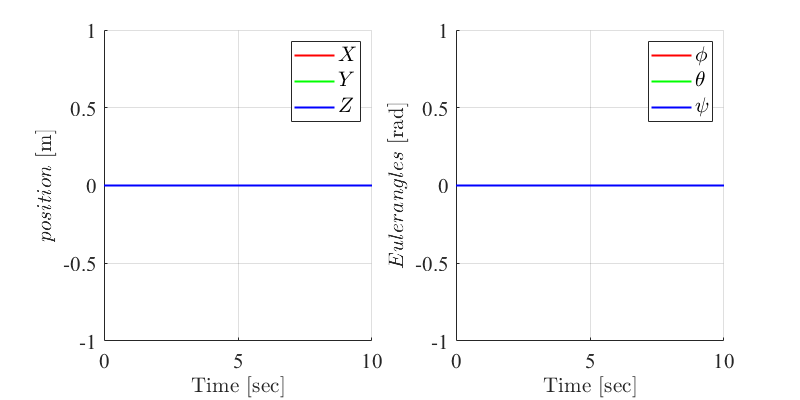

TakeStep = 1; %setting TakeStep 1 take the stepinput, setting TakeStep to 0 take the IN
RPM = uss;
simOut = sim('Exercise_2_2_1_Nonlinear');
plotSimOutput(simOut) % you can find declaration of a function at the end of the file
subplot(1,2,1)
xlim('auto')
ylim([-1,1])

#### Linerizing the model

TakeStep = 0; %setting TakeStep 1 take the stepinput, setting TakeStep to 0 take the IN

% for linearizing the model x0 was used instead of xss, because xss had some
% artefacts from numerical solving (meaning it was not purly equal to zero)
[AA,BB,CC,DD] = linmod('Exercise_2_2_1_Nonlinear',x0,uss);
sys = ss(AA,BB,CC,DD);

t = 0:.1:10; % Time vector
RPM = [0, 0, 0, 0]';
uRPM = RPM*ones(1,length(t));
[y,tOut,xxx] = lsim(sys, uRPM, t);
plotSimOutput(tOut, y') % you can find declaration of a function at the end of the file

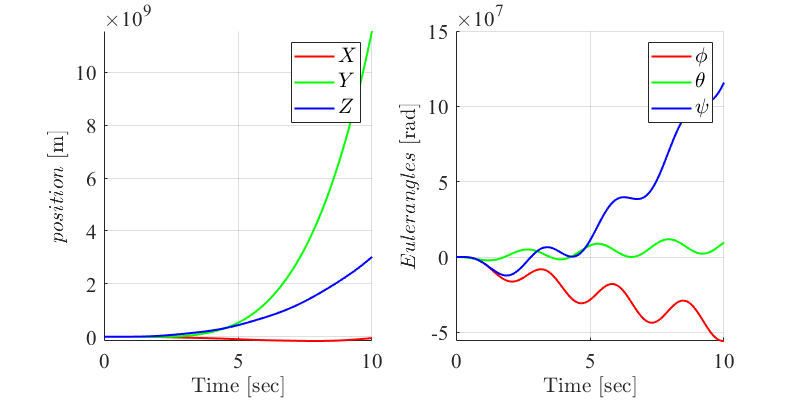

t = 0:.1:10; % Time vector
RPM = [1000, 0, 1000, 0]';
uRPM = RPM*ones(1,length(t));
[y,tOut,xxx] = lsim(sys, uRPM, t);
plotSimOutput(tOut, y') % you can find declaration of a function at the end of the file

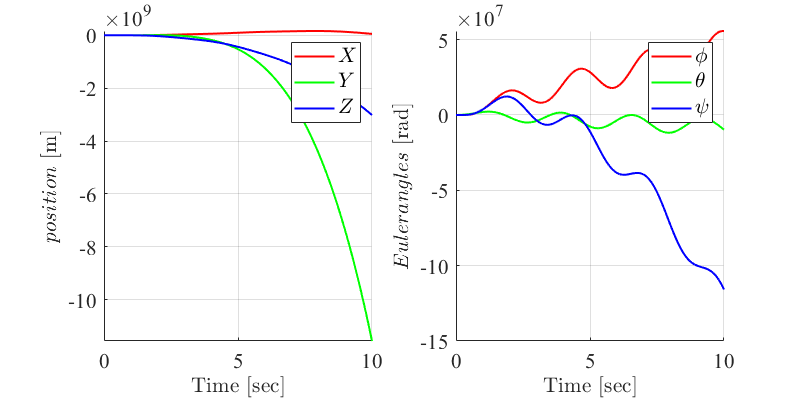

t = 0:.1:10; % Time vector
RPM = [0, 1000, 0, 1000]';
uRPM = RPM*ones(1,length(t));
[y,tOut,xxx] = lsim(sys, uRPM, t);
plotSimOutput(tOut, y') % you can find declaration of a function at the end of the file

#### Plotting function

% plotSimOutput(simOut.yout{1}.Values.Time, simOut.yout{1}.Values.Data)

function plotSimOutput(time, data)
        
    posX = data(1,:);
    posY = data(2,:);
    posZ = data(3,:);
    
    angPhi      = data(4,:);
    angTheta    = data(5,:);
    angPsi      = data(6,:);
    
    
    figure, h1 = subplot(1,2,1); set(h1,'FontName','times','FontSize',16)
    hold on, grid on
    plot(time, posX,'r', time, posY,'g', time, posZ,'b','LineWidth',1.5)
    xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')
    ylabel('$position$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
    legend('$X$', '$Y$', '$Z$', 'FontName','times','FontSize',16,'Interpreter','latex')
    h2 = subplot(1,2,2); set(h2,'FontName','times','FontSize',16)
    hold on, grid on
    plot(time, angPhi,'r', time, angTheta,'g', time, angPsi,'b', 'LineWidth',1.5)
    xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')
    ylabel('$Euler angles$ [rad]','FontName','times','FontSize',16,'Interpreter','latex')
    legend('$\phi$', '$\theta$', '$\psi$', 'FontName','times','FontSize',16,'Interpreter','latex')
    set(gcf,'units','points','position',[0,0,600,300])
end